## Temperature Control Lab Activity

Vaccine production involves innoculating viral material within a host cuture. The viral material will denature if the temperature deviates from the setpoint at any given time for the incubation process. We will use the TCLab to simulate the incubator for the vaccine.

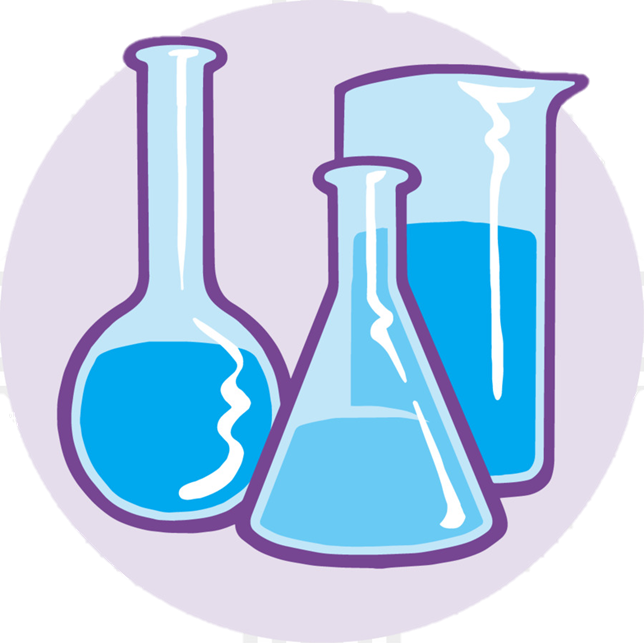

To optimize the ammount of vacine produced, tune the PID to maximize time at the setpoint. First, simulate the TCLab unit and tune the parameters for the PID. Then, use the parameters from the simulation to control the temperature control lab at 40 C for 3 minutes, and 30 C for three minutes afterward.

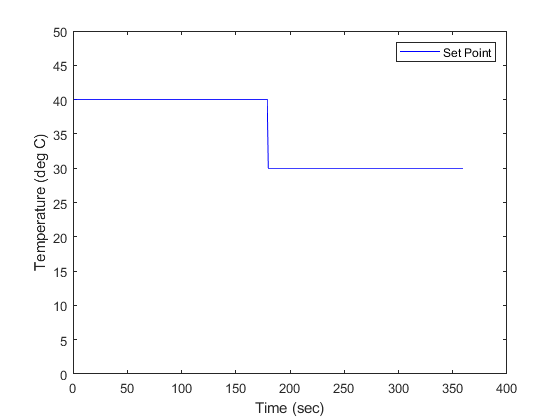

## Simulation

#### PID Controller Equation


$$e(t) = SP - PV$$



$$u(t) = u_{bias} + K_ce(t) + \frac{K_c}{\tau_I}\int_0^te(t)dt-K_c\tau_D\frac{d(PV)}{dt}$$


Find values for $K_c$, $\tau_I$, and $\tau_D$ that minimize error in the simulation below

clc; clear all; close all;
Kc = 6

Kc = 6

tauI = 65

tauI = 65

tauD =  0

tauD = 0

n = 60 * 6;

% initialize arrays
time = linspace(1, n, n);
setpoint = ones(n, 1) * 40;
setpoint(180:end) = 30;
PV = ones(n, 1) * 25;
u = zeros(n, 1);
error = zeros(n, 1);
Ierror = 0;
prev_time = 0;

min = 0;
max = 100;

for i = 1:n
    % PID Controller
    e = setpoint(i) - PV(i);
    error(i) = e;
    Ierror = Ierror + e;
    if i ~= 1
        dPVdt = (PV(i) - PV(i-1)) / (time(i) - time(i-1));
    else
        dPVdt = 0;
    end
    
    P = Kc * e;
    I = Kc / tauI * Ierror;
    D = Kc * tauD * dPVdt;
    u(i) = P + I - D;
    
    % Anti-reset windup
    if u(i) > max
        u(i) = max;
        Ierror = Ierror - e;
    elseif u(i) < min
        u(i) = min;
        Ierror = Ierror - e;
    end
    
    % heater
    % replace with analytic solution
    % Noise with 1 deg http://apmonitor.com/pdc/index.php/Main/FirstOrderSystems

    
    PV(i+1) = arduino_analytic(u(i));
end
fprintf('Error: %E deg s', Ierror)

Error: 6.579961E+01 deg s

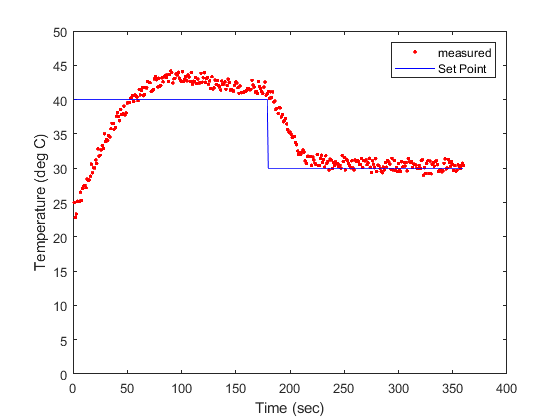


% graph
figure(1)
plot(time, PV(1:end-1), 'r.')
hold on;
plot(time, setpoint, 'b-')
ylim([0 50])
hold on;
xlabel('Time (sec)')
ylabel('Temperature (deg C)')
legend({'measured' 'Set Point'})

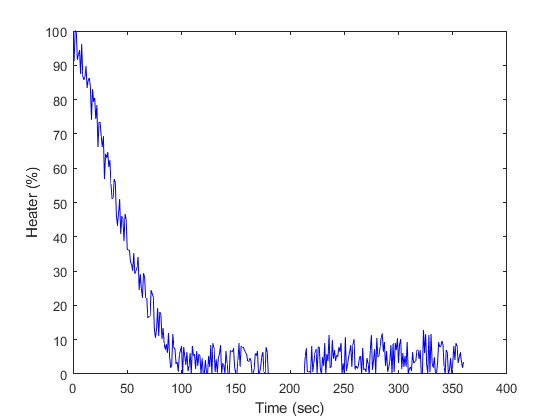


figure(2)
plot(time, u, 'b-')
xlabel('Time (sec)')
ylabel('Heater (%)')
hold off;

## Physical Verification

Verify your simulation by using the same parameters with the TCLab

Kc = 9

Kc = 9

tauI = 135

tauI = 135

tauD = 0

tauD = 0

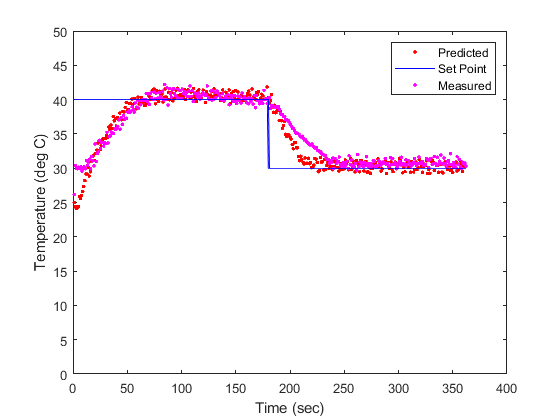

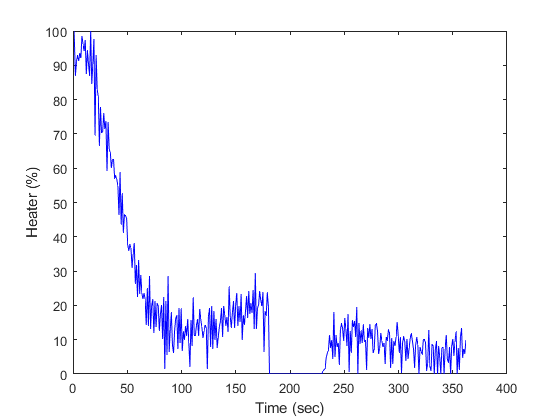

n = 60 * 6;

% initialize arrays
time = zeros(n);
setpoint = ones(n) * 40;
setpoint(180:end) = 30;
PV = zeros(n);
u = zeros(n);
error = zeros(n);
Ierror = 0;
prev_time = 0;

min = 0;
max = 100;

lab = tclab;
tic
for i = 1:n
    % timer
    while toc - prev_time <1
        pause(.01)
    end
    time(i) = toc;
    prev_time = time(i);
    
    % PID Controller
    PV(i) = lab.T1;
    e = setpoint(i) - PV(i);
    error(i) = e;
    Ierror = Ierror + e;
    if i ~= 1
        dPVdt = (PV(i) - PV(i-1)) / (time(i) - time(i-1));
    else
        dPVdt = 0;
    end
    
    P = Kc * e;
    I = Kc / tauI * Ierror;
    D = Kc * tauD * dPVdt;
    u(i) = P + I - D;
    
    % Anti-reset windup
    if u(i) > max
        u(i) = max;
        Ierror = Ierror - e;
    elseif u(i) < min
        u(i) = min;
        Ierror = Ierror - e;
    end
    
    % heater
    lab.Q1(u(i));
    
    % graph
    figure(1)
    plot(time(1:i), PV(1:i), 'm.')
    hold on;
    plot(time(1:i), setpoint(1:i), 'b-')
    hold on;
    xlabel('Time (sec)')
    ylabel('Temperature (deg C)')
    legend({'Predicted', 'Set Point', 'Measured'})
    hold on;
    
    figure(2)
    plot(time(1:i), u(1:i), 'b-')
    xlim([0 400])
    hold on;
    xlabel('Time (sec)')
    ylabel('Heater (%)')
    hold off;
    fname = sprintf ( 'TCLabTrial %i.png', n );
    saveas(gcf,fname);
    
end

lab.off();
clear lab;


% Functions for later use
% Ardiono ODE

function Tnew = arduino_analytic(heater)

persistent icount T0

if (isempty(icount))
    % set initial condition
    T0 = 23;
    icount = 0;
end

Kp = 0.9;
taup = 190.0;
if heater > 0
    T0 = heater * Kp * (1.0-exp(-(1)/taup)) + T0;
else
    T0 = T0 - .3;
end
Tnew = T0 + 2*rand-1;
icount = icount + 1;
end

% function TC = arduino_sim(heater)
% 
% persistent T0 icount
% 
% if (isempty(icount)),
%     % set initial condition
%     T0 = 23+273.15;
%     icount = 0;
% end
% 
% % increment counter
% icount = icount + 1;
% T = arduino_analytic(x,heater);
% TK = T;
% T0 = TK;
% 
% noise = (rand()-0.5)*3.0;
% TC = TK - 273.15 + noise;
% 
% end